Channel simulation

maxValue = 0.8;
minValue = -maxValue;
multi_path_num = 5;
randomNumbers_real = minValue + (maxValue - minValue) * rand(1, multi_path_num);
randomNumbers_imag = minValue + (maxValue - minValue) * rand(1, multi_path_num);

mpChan = [randomNumbers_real'+i.*randomNumbers_imag']  % multipath channel

mpChan =    0.2716 - 0.2445i
  -0.1000 + 0.7823i
   0.6063 - 0.7758i
   0.6285 - 0.3753i
   0.3851 + 0.2988i


%plot(mpChan,"*")

SNR = 22   % dB, signal-to-noise ratio of AWGN

SNR = 22

initialization

nullIdx = [];
numCarr = 1024;
cycPre = 64;
modOrder = 4;  % for 4-QAM
% pilot_len = 8;
bitsPerSymbol = log2(modOrder)

bitsPerSymbol = 2


ScramblerBase = 2;
ScramblerPolynomial = [1 1 1 0 1];
ScramblerInitialConditions = [0 0 0 0];

GB_len = numCarr/16;
left_gb = 1:GB_len

left_gb =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


right_gb = (numCarr-GB_len+1):numCarr

right_gb =          961         962         963         964         965         966         967         968         969         970         971         972         973         974         975         976         977         978         979         980         981         982         983         984         985         986         987         988         989         990         991         992         993         994         995         996         997         998         999        1000        1001        1002        1003        1004        1005        1006        1007        1008        1009        1010


if mod(numCarr,2) == 0
    mid_guard = (numCarr/2)+1
else
    mid_guard = (numCarr+1)/2
end

mid_guard = 513


nullIdx = [left_gb, mid_guard, right_gb]'

nullIdx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10




read_pilot = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\My_Pilot.mat','My_Pilot_Bits','my_QAM_pilot','My_Pilot')

read_pilot = 包含以下字段的 struct :
    My_Pilot_Bits: [1790×1 double]
     my_QAM_pilot: [895×1 double]
         My_Pilot: [1088×1 double]


pilot = read_pilot.My_Pilot

pilot =   -0.0122 + 0.0051i
   0.0056 + 0.0014i
  -0.0119 + 0.0162i
  -0.0212 + 0.0027i
  -0.0213 + 0.0174i
   0.0060 + 0.0029i
   0.0093 - 0.0466i
  -0.0136 - 0.0328i
  -0.0098 + 0.0234i
   0.0102 + 0.0346i


my_QAM_pilot = read_pilot.my_QAM_pilot

my_QAM_pilot =   -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i


My_Pilot_Bits = read_pilot.My_Pilot_Bits

My_Pilot_Bits =      0
     0
     1
     0
     1
     1
     0
     1
     0
     0



numDataCarrs = numCarr-length(nullIdx)

numDataCarrs = 895

pilotIdx= 1:numDataCarrs

pilotIdx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50



read_bit = load('D:\Bristol\23-24\Individual Project\20240410_2\Tx2\4QAM\My_data.mat','My_data')

read_bit = 包含以下字段的 struct :
    My_data: [1790×1 double]


test = read_bit.My_data

test =      0
     0
     1
     0
     0
     0
     1
     0
     1
     0


% my_data = test
% test = my_Scrambler(test)

% test(pilot_place) = pilot
% test = zeros(numDataCarrs*bitsPerSymbol,1)
% size(test)
% test(125) = 1

% raw_bits = textread('D:\Bristol\23-24\Project\Hardware\Simpler\Tx1\tx_bits.txt', '%d', 'delimiter', ' ');
% barker = [-1; -1; -1; 1; 1; -1; 1; 1];

QAM Modulation

my_QAM = qammod(test,modOrder,"InputType","bit")

my_QAM =   -1.0000 + 1.0000i
   1.0000 + 1.0000i
  -1.0000 + 1.0000i
   1.0000 + 1.0000i
   1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
   1.0000 - 1.0000i
   1.0000 + 1.0000i
  -1.0000 + 1.0000i



%scatterplot(my_QAM)
my_test_QAM = my_QAM(pilotIdx)

my_test_QAM =   -1.0000 + 1.0000i
   1.0000 + 1.0000i
  -1.0000 + 1.0000i
   1.0000 + 1.0000i
   1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
   1.0000 - 1.0000i
   1.0000 + 1.0000i
  -1.0000 + 1.0000i


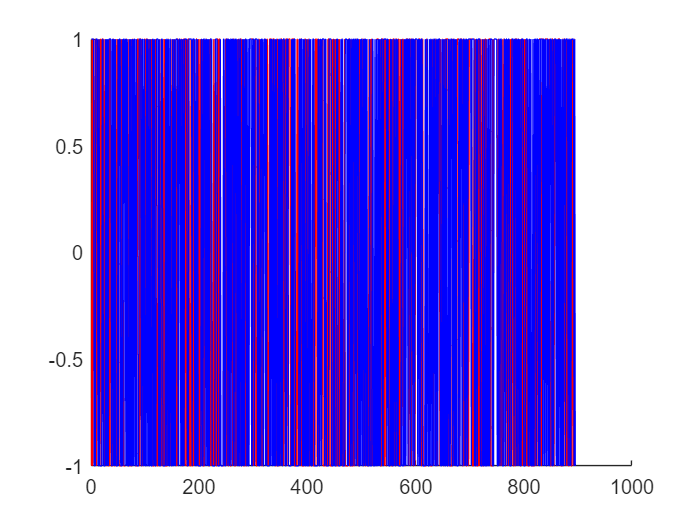


figure()
hold on
plot(real(my_QAM),'r')
plot(imag(my_QAM),'b')
hold off


% pilots = qammod(pilot,modOrder,"InputType","bit","UnitAveragePower",true)
% 
% nnz(my_test_QAM ~= pilots)

read_header = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\complexArray.mat',"my_ofdm");
my_header = read_header.my_ofdm

my_header =   -1.3868 + 0.1609i
  -0.3526 - 0.4706i
   0.2521 + 0.3226i
   0.1402 + 0.3603i
   0.2220 + 0.6640i
  -0.1553 + 0.0097i
  -0.1274 - 0.1854i
   0.2864 + 0.1089i
   0.3186 - 0.2367i
  -0.1596 - 0.0461i



% read_tail = load('my_tail.mat','my_tail');
% my_tail = read_tail.my_tail;

OFDM Modulation

my_ofdm = ofdmmod(my_QAM,numCarr,cycPre,nullIdx)

my_ofdm =   -0.0148 + 0.0149i
  -0.0055 - 0.0058i
   0.0237 - 0.0269i
   0.0037 - 0.0371i
   0.0029 - 0.0407i
  -0.0273 - 0.0565i
  -0.0175 - 0.0296i
  -0.0229 + 0.0371i
  -0.0510 + 0.0023i
  -0.0098 + 0.0040i


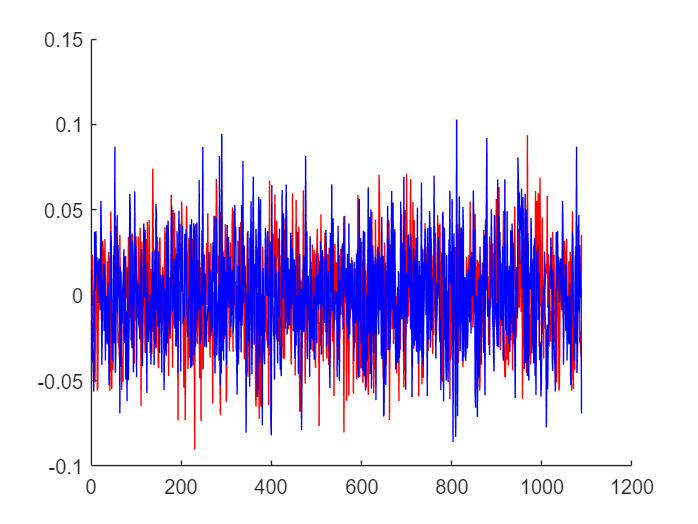


figure()
hold on
plot(real(my_ofdm),'r')
plot(imag(my_ofdm),'b')
hold off


size_my_ofdm = size(my_ofdm)

size_my_ofdm =         1088           1


my_ofdm = [pilot;my_ofdm]

my_ofdm =   -0.0122 + 0.0051i
   0.0056 + 0.0014i
  -0.0119 + 0.0162i
  -0.0212 + 0.0027i
  -0.0213 + 0.0174i
   0.0060 + 0.0029i
   0.0093 - 0.0466i
  -0.0136 - 0.0328i
  -0.0098 + 0.0234i
   0.0102 + 0.0346i


Amplify the Signal

my_real_tx_gain =1 / max(real(my_ofdm))

my_real_tx_gain = 10.6802

my_imag_tx_gain =1 / max(imag(my_ofdm))

my_imag_tx_gain = 9.7227

my_tx_gain = min(my_real_tx_gain,my_imag_tx_gain)

my_tx_gain = 9.7227


my_ofdm = [my_ofdm].*my_tx_gain;  % to make it bit smaller. to make a larger SNR, remove "/10"

tx_data = [my_header;my_ofdm;zeros(numCarr+cycPre,1)];
% tx_data = [tx_data;zeros(numCarr+cycPre,1)];
size(tx_data)

ans =         3536           1


Apply Multi-channel and AWGN

tx_data = tx_data 

tx_data =   -1.3868 + 0.1609i
  -0.3526 - 0.4706i
   0.2521 + 0.3226i
   0.1402 + 0.3603i
   0.2220 + 0.6640i
  -0.1553 + 0.0097i
  -0.1274 - 0.1854i
   0.2864 + 0.1089i
   0.3186 - 0.2367i
  -0.1596 - 0.0461i


mpChanOut = filter(mpChan,1,tx_data); %apply mutipat

%chanOut = mpChanOut
Rx_sig = awgn(mpChanOut,SNR,"measured") %apply AWGN

Rx_sig =   -0.2946 + 0.3578i
  -0.2080 - 1.1639i
  -0.1425 + 1.0011i
  -1.5156 + 0.8342i
  -0.6913 - 0.3470i
   0.0453 + 0.1120i
   0.7874 + 0.4082i
   0.4877 + 0.5866i
  -0.5034 + 0.4412i
   0.1348 + 0.0191i


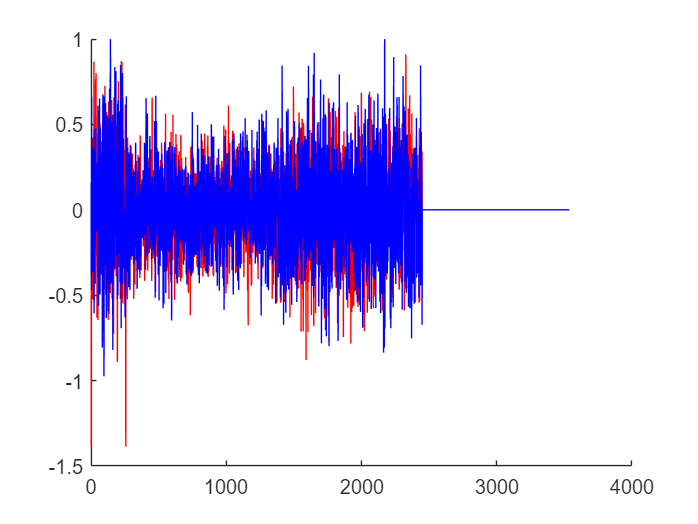

% Rx_sig = mpChanOut

figure()
hold on
plot(real(tx_data),'r')
plot(imag(tx_data),'b')
hold off

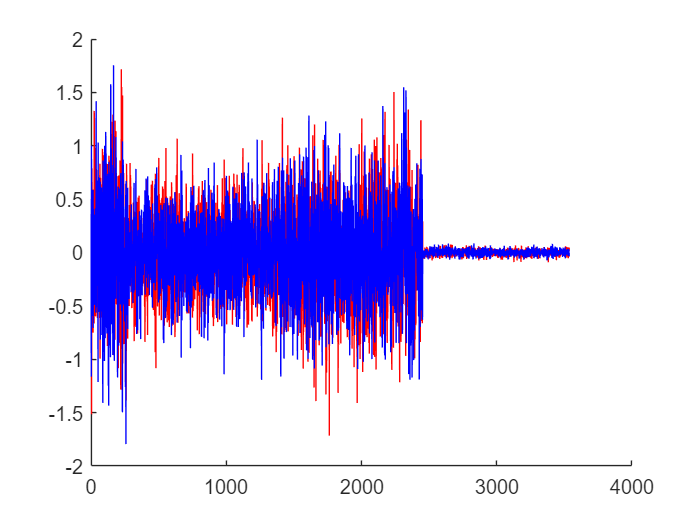


figure()
hold on
plot(real(Rx_sig),'r')
plot(imag(Rx_sig),'b')
hold off

% scatterplot(tx_data)
tx_data = Rx_sig;

## RX Simulation

find header / tail

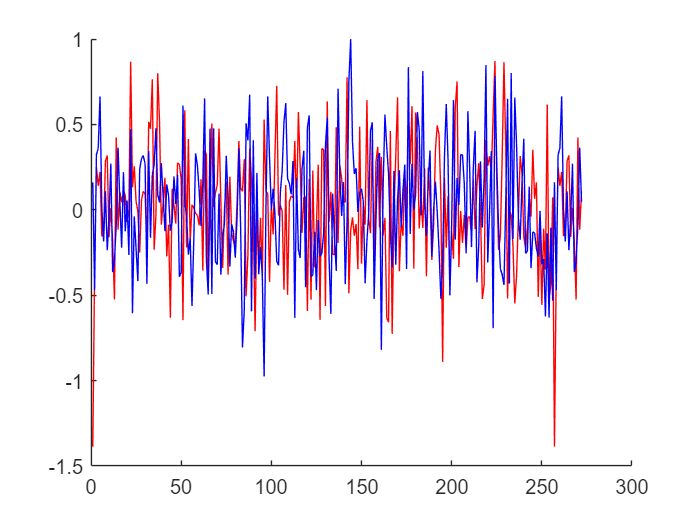

read_header = load('D:\Bristol\23-24\Project\Hardware\Simpler\Tx2\4QAM\complexArray.mat',"my_ofdm");
my_header = read_header.my_ofdm;

figure()
hold on
plot(real(my_header),'r')
plot(imag(my_header),'b')
hold off


head_detec = comm.PreambleDetector('Input','Symbol','Preamble',my_header,'Threshold',2,'Detections','All')

head_detec =   comm.PreambleDetector - 属性:

         Input: 'Symbol'
      Preamble: [272×1 double]
     Threshold: 2
    Detections: 'All'


[head_idx,head_detmet] = head_detec(tx_data)

head_idx =     17
    18
    19
    20
    21
    23
    25
    34
    35
    40


head_detmet =     0.0538
    0.1006
    0.6903
    0.7604
    1.3890
    0.4544
    1.3972
    1.0319
    0.9854
    0.6586


[head_maxCorr, head_maxIndex] = max(head_detmet)

head_maxCorr = 67.6501

head_maxIndex = 274


from_head = head_maxIndex+1:head_maxIndex+numCarr+cycPre+length(pilot)

from_head =    275   276   277   278   279   280   281   282   283   284   285   286   287   288   289   290   291   292   293   294   295   296   297   298   299   300   301   302   303   304   305   306   307   308   309   310   311   312   313   314   315   316   317   318   319   320   321   322   323   324


ofdm_received = tx_data(from_head)

ofdm_received =   -0.1417 + 0.3236i
  -0.1145 + 0.0325i
  -0.0092 + 0.0782i
  -0.1811 + 0.1332i
  -0.3739 + 0.2933i
   0.1715 + 0.1544i
  -0.0784 - 0.3194i
  -0.5015 - 0.4356i
  -0.2524 - 0.0679i
   0.4451 + 0.1522i


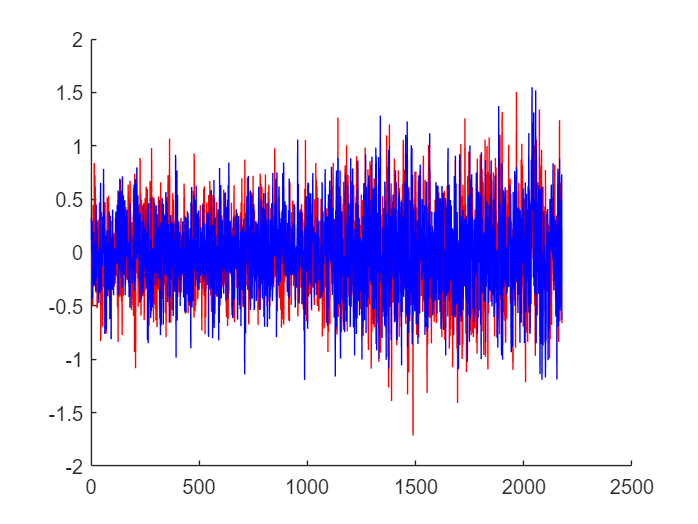


figure()
hold on
plot(real(ofdm_received),'r')
plot(imag(ofdm_received),'b')
hold off

OFDM Demodulation

pilot_received = ofdm_received(1 : numCarr+cycPre);
data_received = ofdm_received(numCarr+cycPre+1 : end);
rxPilots = ofdmdemod(pilot_received,numCarr,cycPre,cycPre,nullIdx)

rxPilots =   -3.2231 +15.9479i
  15.6420 + 3.6790i
   2.0441 -15.6378i
 -16.0806 - 3.3007i
  -4.7061 +17.7790i
 -16.0783 - 3.6006i
   4.0987 -15.8965i
 -15.5715 - 5.1067i
 -16.2601 - 3.6162i
   2.8746 -15.5250i


my_received_data = ofdmdemod(data_received,numCarr,cycPre,cycPre,nullIdx)

my_received_data =   -4.6693 +24.0389i
  22.0260 + 4.4962i
  -5.7493 +22.5344i
  21.5139 + 3.5716i
  22.4278 + 4.6239i
 -22.6368 - 6.3421i
 -24.4439 - 5.1970i
   3.8897 -23.7751i
  23.1308 + 5.8524i
  -4.2084 +21.7229i


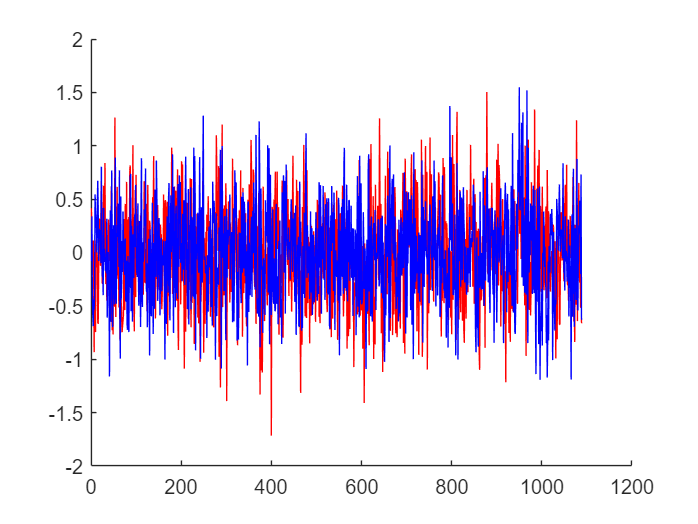


% ofdm_deout = [ofdm_deout(:,1);ofdm_deout(:,2)]

figure()
hold on
plot(real(data_received),'r')
plot(imag(data_received),'b')
hold off


% my_received_data = ofdmdemod(data_received,numCarr,cycPre,cycPre,nullIdx)
% test_demod_data = qamdemod(my_received_data,4,"OutputType","bit","UnitAveragePower",true)
% nnz(test~=qamDemodOut)

% figure()
% hold on
% plot(real(test_demod_data),'r')
% plot(imag(test_demod_data),'b')
% hold off

Channel Estimation

estimatedChannelResponse = rxPilots ./ my_QAM_pilot;
temp = 20.*log10(abs(estimatedChannelResponse))

temp =    24.2279
   24.1197
   23.9571
   24.3053
   25.2923
   24.3373
   24.3056
   24.2902
   24.4321
   23.9670


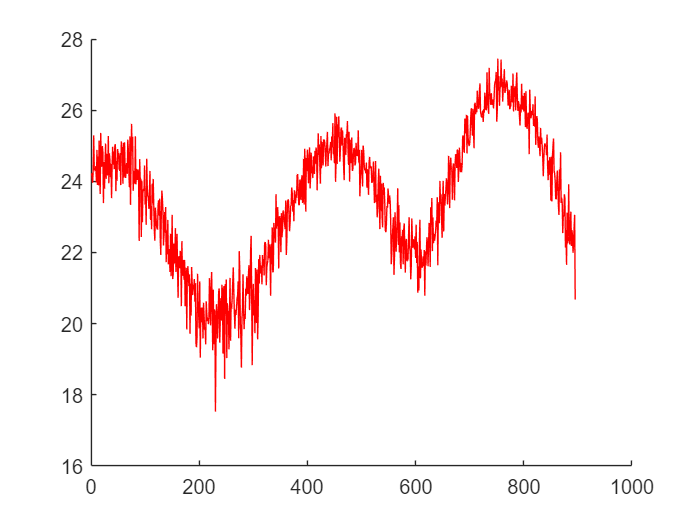


figure()
hold on
plot(real(temp),'r')
hold off


% test pilot estimation
pilot_estimation = rxPilots ./ estimatedChannelResponse

pilot_estimation =   -0.7071 + 0.7071i
   0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i


test_pilot = qamdemod(pilot_estimation,modOrder,"OutputType","bit")

test_pilot =      0
     0
     1
     0
     1
     1
     0
     1
     0
     0


nnz(test_pilot~=My_Pilot_Bits)

ans = 0

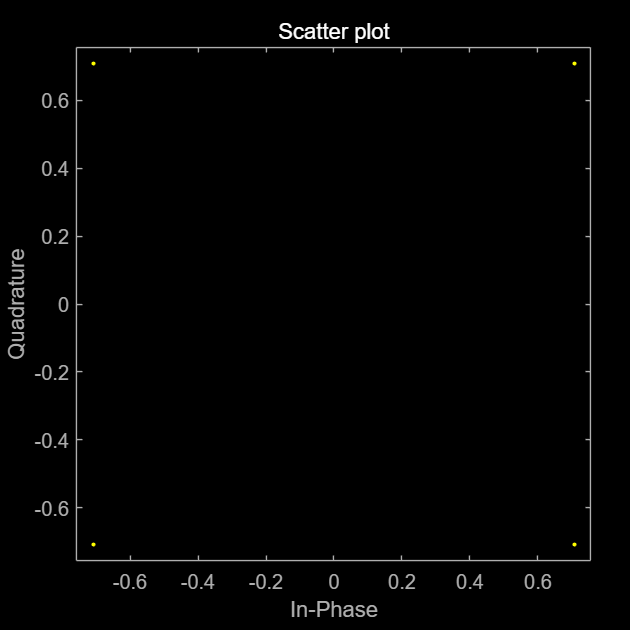

scatterplot(pilot_estimation)


equalizedSignal = my_received_data ./ estimatedChannelResponse

equalizedSignal =   -1.0562 + 1.0723i
   1.0181 + 0.9595i
  -1.1599 + 0.9106i
   0.9743 + 0.9031i
   0.9279 + 0.8303i
  -0.9542 - 1.0608i
  -1.1215 - 1.0293i
   0.8669 - 1.1873i
   0.9831 + 1.0418i
  -0.9991 + 0.9827i


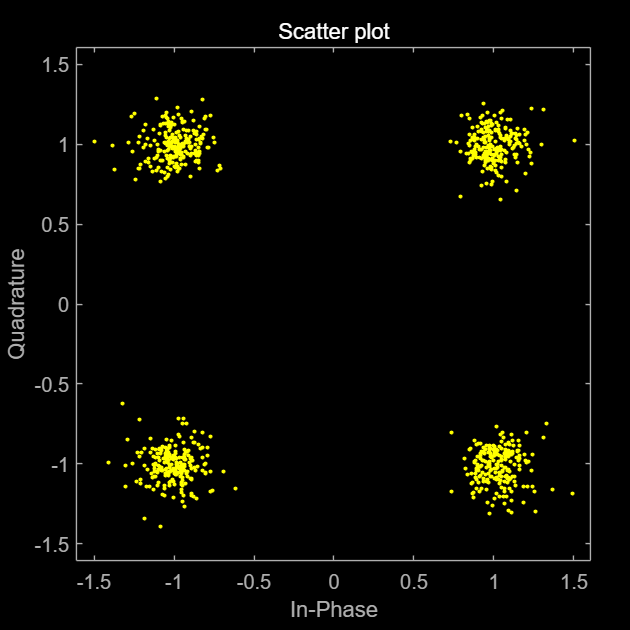

scatterplot(equalizedSignal)


qamDemodOut = qamdemod(equalizedSignal,modOrder,"OutputType","bit")

qamDemodOut =      0
     0
     1
     0
     0
     0
     1
     0
     1
     0



% qamDemodOut = my_Descrambler(qamDemodOut)
nnz(test~=qamDemodOut)

ans = 0


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Channel Estimation
% rxPilots = ofdm_deout(pilotIdx)
silent_period = Rx_sig(head_maxIndex+(numCarr+cycPre)*2+1 : round(head_maxIndex+(numCarr+cycPre)*2.9))

silent_period =   -0.1746 - 0.6185i
   0.2899 - 0.1761i
  -0.0436 + 0.0231i
  -0.0012 + 0.0052i
   0.0077 - 0.0163i
   0.0081 + 0.0116i
   0.0031 - 0.0148i
  -0.0459 + 0.0072i
   0.0185 - 0.0209i
   0.0075 + 0.0173i


sigma_n_squared = var(silent_period)

sigma_n_squared = 0.0020


channel_response_estimate = rxPilots ./ my_QAM_pilot;

sigma_H_squared = var(abs(channel_response_estimate))

sigma_H_squared = 10.3726


H_est_MMSE = zeros(numCarr-length(nullIdx),1);

Y_over_X = rxPilots ./ my_QAM_pilot;
show_MMSE = (sigma_H_squared / (sigma_H_squared + sigma_n_squared));

H_est_MMSE = (sigma_H_squared / (sigma_H_squared + sigma_n_squared)) .* Y_over_X;


% H_est_full_MMSE = interp1(pilotIdx, H_est_MMSE, 1:(numCarr-length(nullIdx)), 'linear', 'extrap');

equalizedSignal_MMSE = my_received_data ./ H_est_MMSE;
qamDemodOut_MMSE = qamdemod(equalizedSignal_MMSE,modOrder,"OutputType","bit")

qamDemodOut_MMSE =      0
     0
     1
     0
     0
     0
     1
     0
     1
     0


my_difference = nnz(test~=qamDemodOut)

my_difference = 0

nnz(test~=qamDemodOut_MMSE)

ans = 0

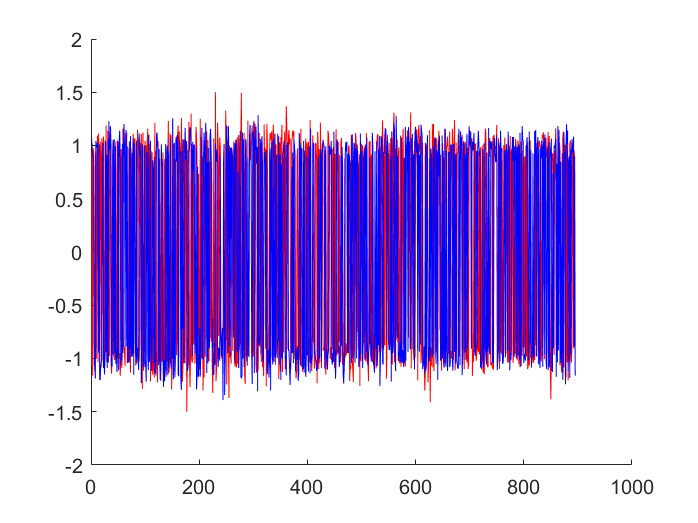

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% specAn = dsp.SpectrumAnalyzer("NumInputPorts",1, ...
%     "SpectralAverages",50,...
%     "ShowLegend",true);
% specAn(equalizedSignal_MMSE)

figure()
hold on
plot(real(equalizedSignal),'r')
plot(imag(equalizedSignal),'b')
hold off



figure()
hold on
plot(real(equalizedSignal),'r')
plot(imag(equalizedSignal),'b')
hold off

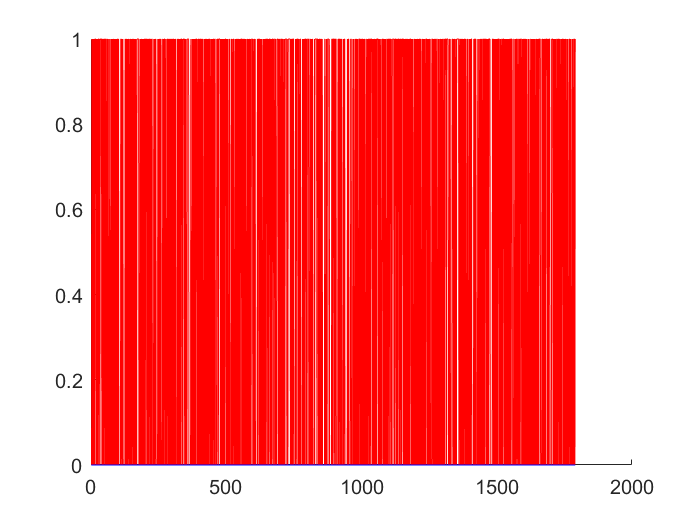


figure()
hold on
plot(real(qamDemodOut),'r')
plot(imag(qamDemodOut),'b')
hold off


figure()
hold on
plot(real(qamDemodOut_MMSE),'r')
plot(imag(qamDemodOut_MMSE),'b')
hold off